#### Linear advection simulation using SSPRK3L2R1 scheme and calculating numerical amplification factor

One-Dimesional linear convection equation is:


$$\frac{\partial u}{\partial t}+c\frac{\partial u}{\partial x}=0$$


Discretizng using RK2L2R1 gives


$$u^{(1)} = u^n - \frac{c\Delta t}{6\Delta x}\left( u^{n}_{i-2}-6u^{n}_{i-1}+3u^{n}_{i}+2u^{n}_{i+1}\right), \\ 
u^{(2)} = \frac{3}{4}u^n +\frac{1}{4}u^{(1)}- \frac{c\Delta t}{4\times 6\Delta x}\left( u^{(1)}_{i-2}-6u^{(1)}_{i-1}+3u^{(1)}_{i}+2u^{(1)}_{i+1}\right),  \\ 
u^{n+1}=\frac{1}{3}u^n+\frac{2}{3}u^{(2)} - \frac{2c\Delta t}{3\times6\Delta x}\left( u^{(2)}_{i-2}-6u^{(2)}_{i-1}+3u^{(2)}_{i}+2u^{(2)}_{i+1}\right).$$


Converting the above equation in the spectral plane, we get


$$\tilde{U}^{(1)} = \tilde{U} - \frac{CFL}{6}\left(\tilde{U}\exp(-2ikh)-6\tilde{U}\exp(-ikh)+ 3\tilde{U}+2\tilde{U}\exp(ikh)\right), \\ 
	\tilde{U}^{(2)} = \frac{3}{4}\tilde{U} +\frac{1}{4}\tilde{U}^{(1)}- \frac{CFL}{4\times6}\left(\tilde{U}^{(1)}\exp(-2ikh)-6\tilde{U}^{(1)}\exp(-ikh)+ 3\tilde{U}^{(1)}+2\tilde{U}^{(1)}\exp(ikh)\right) , \\ 
	\tilde{U}^{n+1}=\frac{1}{3}\tilde{U}+\frac{2}{3}\tilde{U}^{(2)} - \frac{2CFL}{3\times6}\left(\tilde{U}^{(2)}\exp(-2ikh)-6\tilde{U}^{(2)}\exp(-ikh)+ 3\tilde{U}^{(2)}+2\tilde{U}^{(2)}\exp(ikh)\right)$$


Numerical amplification factor is:


$$G^{(1)} = 1 - \frac{CFL}{6}\left(\exp(-2ikh)-6\exp(-ikh)+ 3+2\exp(ikh)\right), \\
G^{(2)} = \frac{3}{4} +\frac{1}{4}G^{(1)}- \frac{CFL}{4\times6}\left(G^{(1)}\exp(-2ikh)-6G^{(1)}\exp(-ikh)+ 3G^{(1)}+2G^{(1)}\exp(ikh)\right), \\ 
G_{SSPRK3-L2R1}=\frac{1}{3}+\frac{2}{3}G^{(2)} - \frac{2CFL}{3\times6}\left(G^{(2)}\exp(-2ikh)-6G^{(2)}\exp(-ikh)+ 3G^{(2)}+2G^{(2)}\exp(ikh)\right)$$


clc
clear all
close all
format long

Domain Length is 2 $\pi$ and divided into 101 points. Initial condtion used is sin(x) with wave number 1.

l=2*pi;
n=101;
k=1;
x=linspace(0,l,n);
y=sin(k*x);

Delete the last point to avoid repetion, because $y(2\pi)=y(0)$

x(end)=[];
y(end)=[];
dx=l/(n-1);

Flow time is 5 s and calculate $\Delta t$ from CFL number

T=5;
c=1;
cfl=0.5;
dt=cfl/c*dx;
nt=round(T/dt);

Solving PDE

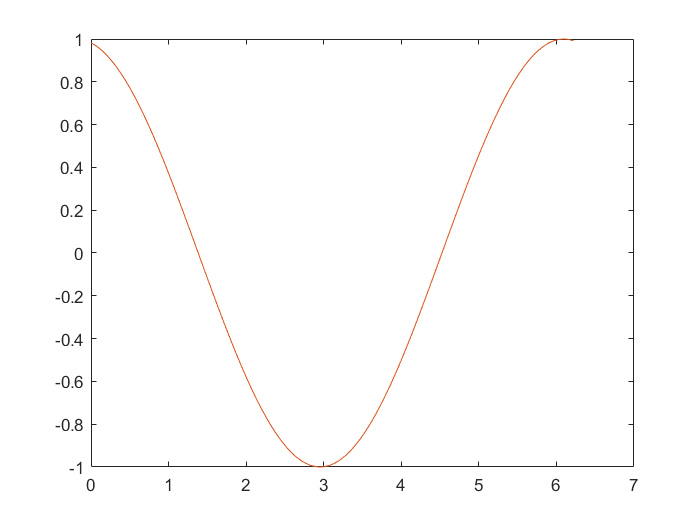

qw1=round(nt/10); % plot number of framed

for i =1:nt
    y0=y;

        dy=PerDerivative_L2R1(y,dx);
        y=y0-1/1*c*dt*dy;
        dy=PerDerivative_L2R1(y,dx);
        y=0.75*y0+0.25*(y-c*dt*dy);
        dy=PerDerivative_L2R1(y,dx);
        yn=(y0+2*(y-1*c*dt*dy))/3;
        t1=dt*(i);
        yex=sin(k*(x-c*t1)) ; % exact solution

        y=yn;

if mod(i,qw1)==0
    plot(x,yn,x,yex)
    drawnow
end
Fs=1/dx;
Ts=dx;
[YfreqD,freqRng] = positiveFFT(y,Fs,yex);%FFT calculating function
fft_mag(i)=max((YfreqD)); % storing dominent frequncy
end

Numerical amplification factor is:

gsim=mean(fft_mag(2:end)./fft_mag(1:end-1));
fprintf('Numerical amplification factor from simulation =\n %f%+fj\n',real(gsim),imag(gsim));

Numerical amplification factor from simulation =
 0.999506-0.031411j


Theoritical amplification factor

kh=dx*k;
G_ex2=1-cfl*(exp(-2*1i*kh)-6*exp(-1*1i*kh)+3+2*exp(1*1i*kh))/6;
G_ex1=3/4+1/4*G_ex2-1/4*cfl*G_ex2*(exp(-2*1i*kh)-6*exp(-1*1i*kh)+3+2*exp(1*1i*kh))/6;
G_ex=1/3+2/3*G_ex1-2/3*cfl*G_ex1*(exp(-2*1i*kh)-6*exp(-1*1i*kh)+3+2*exp(1*1i*kh))/6;
G_mag=((G_ex));
fprintf('Numerical amplification factor from theory =\n %f%+fj\n',real(G_ex),imag(G_ex));

Numerical amplification factor from theory =
 0.999506-0.031411j


Plotting the frequncy 

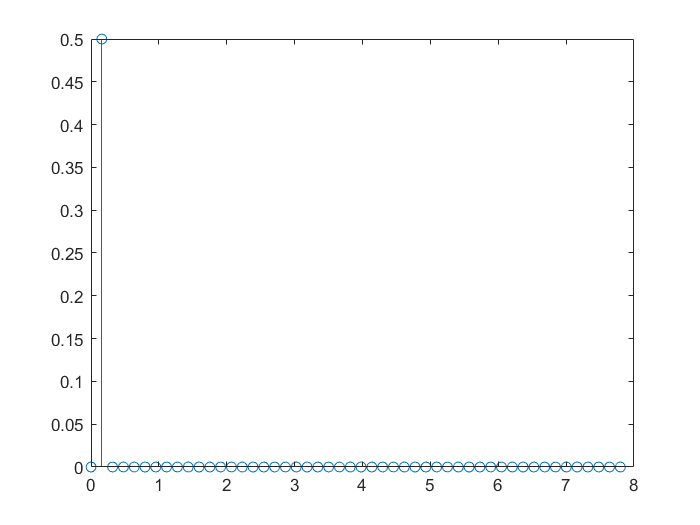

stem(freqRng,abs(YfreqD));

[M,I] = max(abs(YfreqD));
fprintf('Frequency of the FFT signal is %f', freqRng(I))

Frequency of the FFT signal is 0.159155

fprintf('Frequency of the input signal is %f', k/2/pi)

Frequency of the input signal is 0.159155